# Trabajo grupal 2 (Métodos Numéricos)

- Sección: 5

- N° de grupo: 2

- Integrante 1 (líder): Carlos Fabrizio Condor Hurtado - 100%        

- Integrante 2:

- Integrante 3: Alejandra Brisa SIlva Salazar - 100%

- Integrante 4: Sanchez Silvera Joseph - 100%

- Integrante 5:

**Observación:** No olvidar añadir el porcentaje de participación.

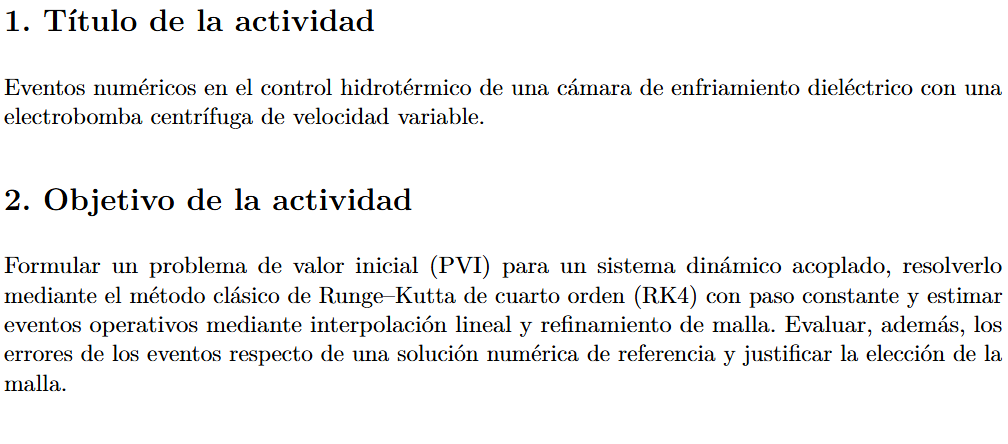

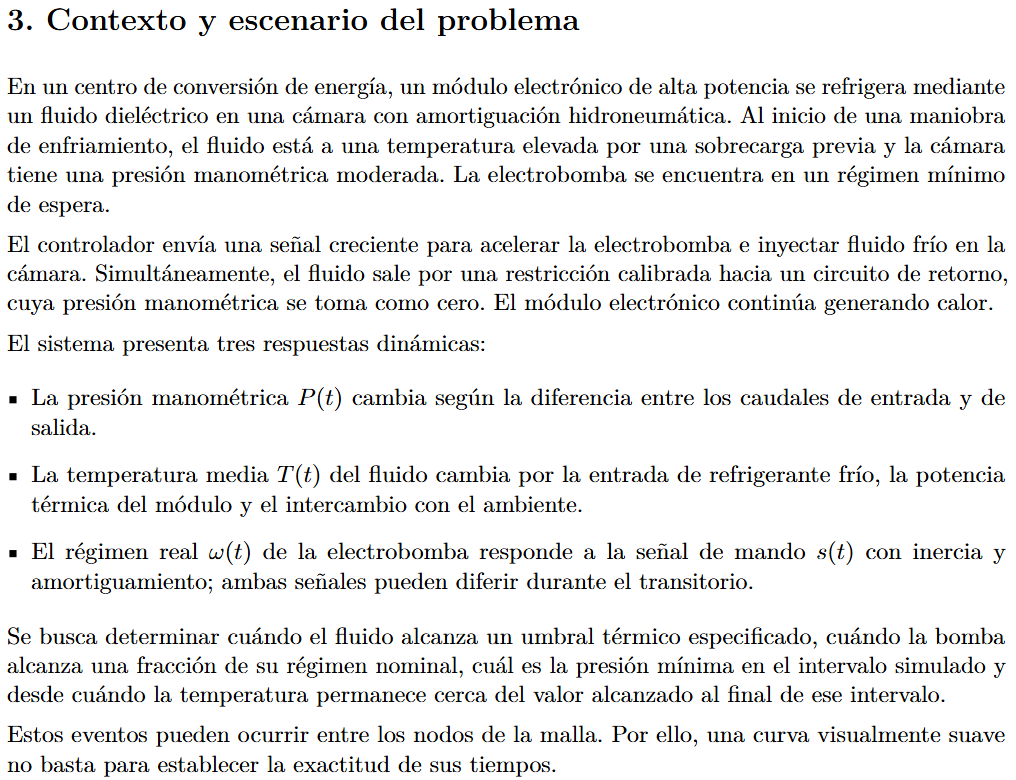

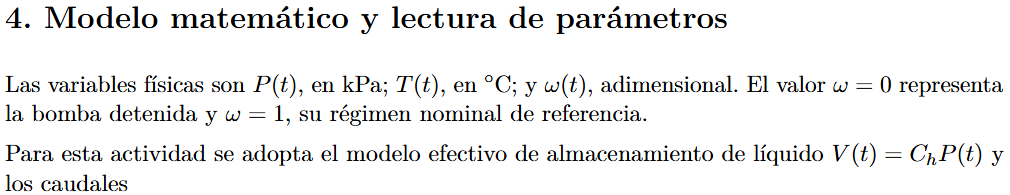

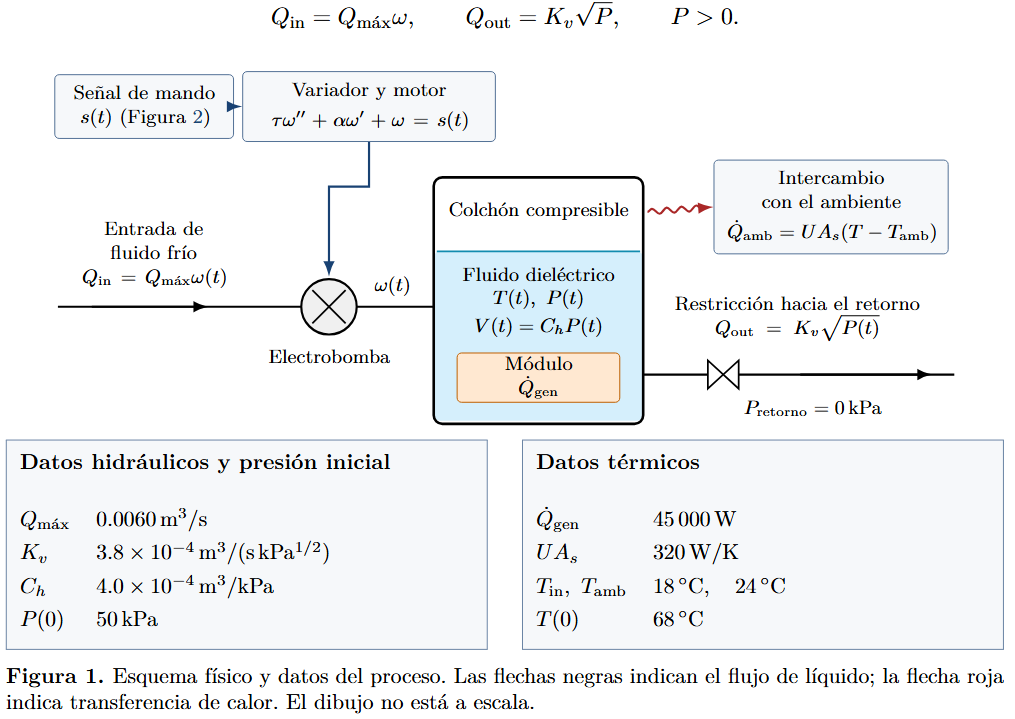

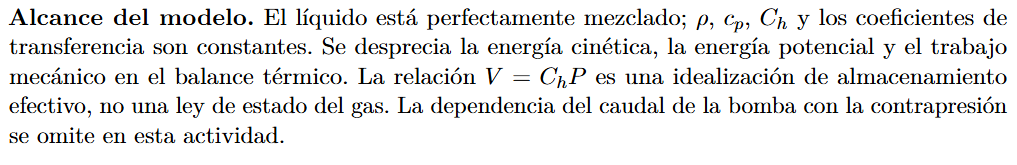

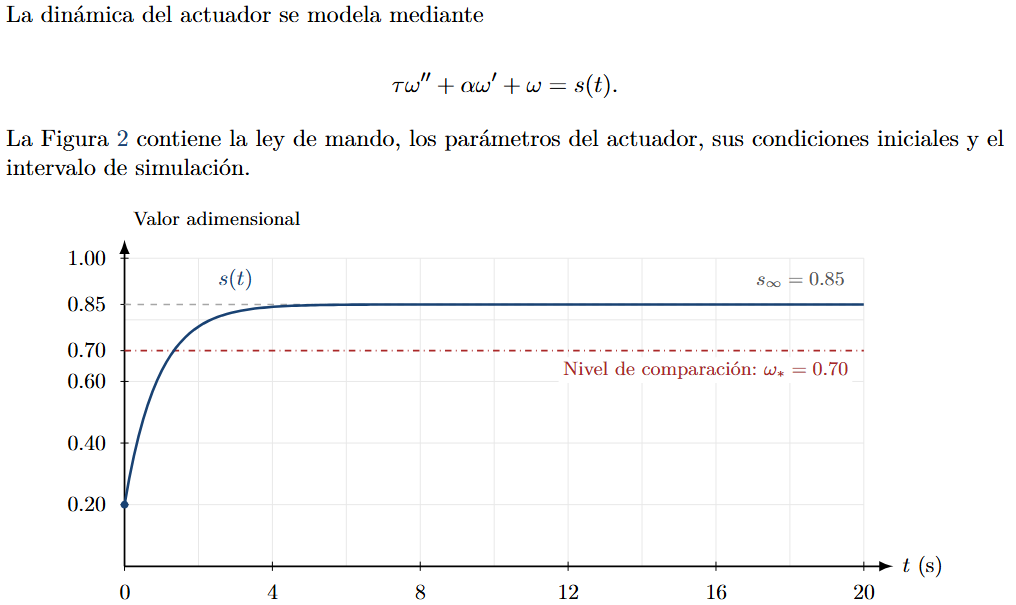

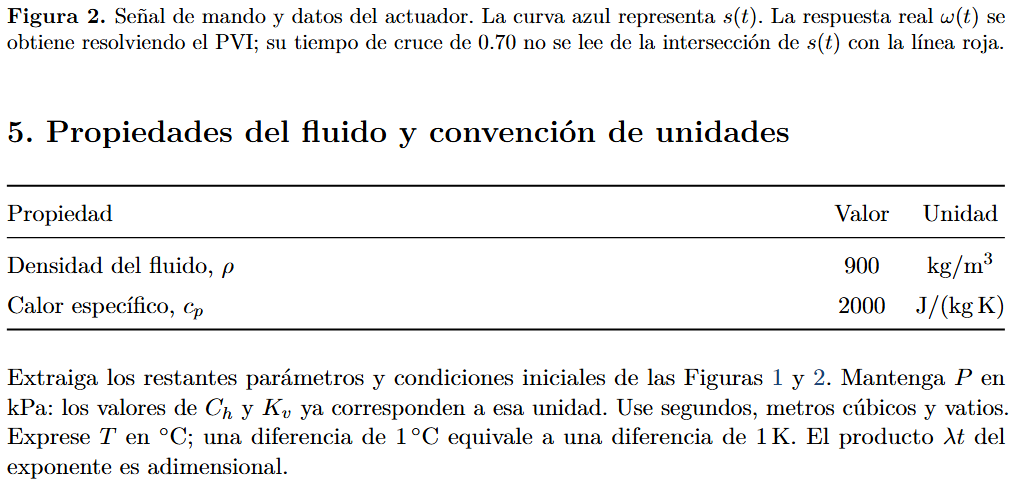

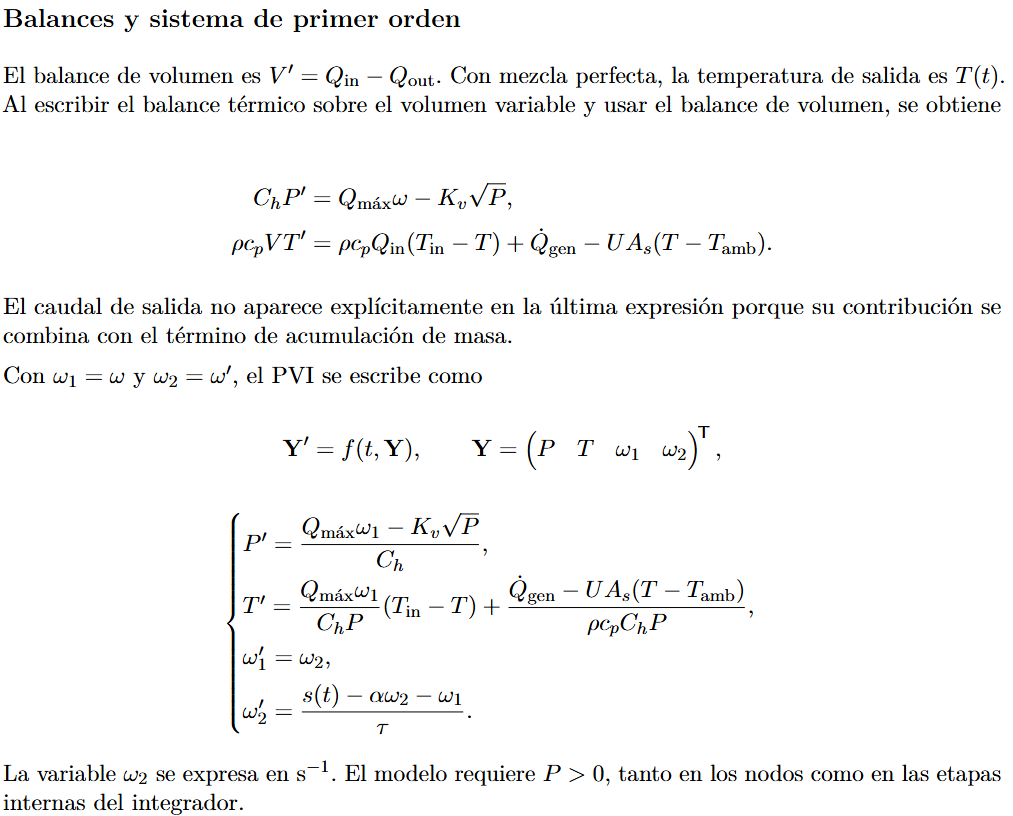

clearvars; clc; close all;

p.Qmax  = 0.0060;    
p.Kv    = 3.8e-4;   
p.Ch    = 4.0e-4;   
p.Qgen  = 45000;     
p.UAs   = 320;      
p.Tin   = 18;        
p.Tamb  = 24;        
p.rho   = 900;       
p.cp    = 2000;      
p.s0    = 0.20;      
p.ds    = 0.65;
p.lam   = 1.10;      
p.tau   = 0.80;     
p.alpha = 1.10;     

t0 = 0;  tf = 20;                 
Y0 = [50; 68; 0.20; 0];           
Ns = [50 100 200 400 800];        
DT = 0.5;                        
Tumbral = 42;  wumbral = 0.70;    

f = @(t,Y) edo_rc02(t,Y,p);
cV = p.rho*p.cp*p.Ch;             
fprintf('P''  = %.4f*w1 - %.4f*sqrt(P)\n', p.Qmax/p.Ch, p.Kv/p.Ch);

P'  = 15.0000*w1 - 0.9500*sqrt(P)


fprintf('T''  = [%.4f*w1*(%.0f - T) + %.4f - %.6f*(T - %.0f)]/P\n', ...
        p.Qmax/p.Ch, p.Tin, p.Qgen/cV, p.UAs/cV, p.Tamb);

T'  = [15.0000*w1*(18 - T) + 62.5000 - 0.444444*(T - 24)]/P


fprintf('w1'' = w2\n');

w1' = w2


fprintf('w2'' = %.4f*s(t) - %.4f*w2 - %.4f*w1\n', 1/p.tau, p.alpha/p.tau, 1/p.tau);

w2' = 1.2500*s(t) - 1.3750*w2 - 1.2500*w1


fprintf('s(t) = %.2f + %.2f*(1 - exp(-%.2f*t))\n', p.s0, p.ds, p.lam);

s(t) = 0.20 + 0.65*(1 - exp(-1.10*t))



disp('Y(0) = [P; T; w1; w2] ='); disp(Y0)

Y(0) = [P; T; w1; w2] =
   50.0000
   68.0000
    0.2000
         0



disp('f(0,Y(0)) ='); disp(f(0,Y0))

f(0,Y(0)) =
   -3.7175
   -2.1411
         0
         0



**1. Significado de los eventos**

tT42 corresponde al primer cruce descendente de 42 °C debido al ingreso de líquido frío, mientras que tω70 indica el primer cruce ascendente de ω = 0.70, considerando la inercia de la bomba mediante el PVI. Por su parte, tP,mín representa la presión mínima global en [t₀, t_f], que ocurre cuando se igualan los caudales (P′ = 0), y test,T indica desde cuándo la temperatura permanece dentro de ±0.5 K respecto a T(t_f), sin que esto implique necesariamente un equilibrio definitivo.

**2. Deducción de la fórmula para t*_lin**

Para encontrar el instante en que la variable alcanza el umbral y*, se iguala la interpolación lineal a dicho valor y luego se despeja el tiempo:

L(t) = y*

yᵢ + [(yᵢ₊₁ − yᵢ)/(tᵢ₊₁ − tᵢ)] · (t − tᵢ) = y*

t*_lin = tᵢ + [(y* − yᵢ)/(yᵢ₊₁ − yᵢ)] · (tᵢ₊₁ − tᵢ)

La condición (yᵢ − y*)(yᵢ₊₁ − y*) < 0 garantiza que los puntos están a lados opuestos del umbral, que yᵢ₊₁ ≠ yᵢ y que la fracción está entre 0 y 1; por eso, el cruce queda dentro del intervalo.

**3. Dirección del cruce y casos especiales**

El cruce es descendente cuando yᵢ > y* > yᵢ₊₁ y ascendente cuando yᵢ < y* < yᵢ₊₁, lo cual también se identifica observando si la diferencia yᵢ₊₁ − yᵢ es negativa o positiva. Si el umbral coincide con un nodo, este se asigna al intervalo que termina en él, usando intervalos semiabiertos, para evitar contarlo dos veces; además, se debe cumplir yᵢ₊₁ ≠ yᵢ para aplicar la fórmula. Si la variable solo toca el umbral sin atravesarlo, no existe un cruce, y si todo el segmento permanece sobre él, tampoco hay un instante único.

**4. Error del integrador frente al de interpolación**

Para una solución suficientemente suave, RK4 presenta un error global de orden O(h⁴), mientras que la interpolación lineal tiene un error de orden O(h²), incluso si los puntos son exactos. Por ello, en un cruce simple, donde y′(t*) ≠ 0, se espera que el error del tiempo de cruce sea O(h²), es decir, que al reducir h a la mitad disminuya aproximadamente cuatro veces. Esto también explica por qué una gráfica puede verse suave sin garantizar tiempos precisos: un pequeño error δy puede generar un cambio importante en el tiempo, según δt ≈ δy/|y′(t*)|, especialmente cuando la pendiente en el cruce es pequeña.

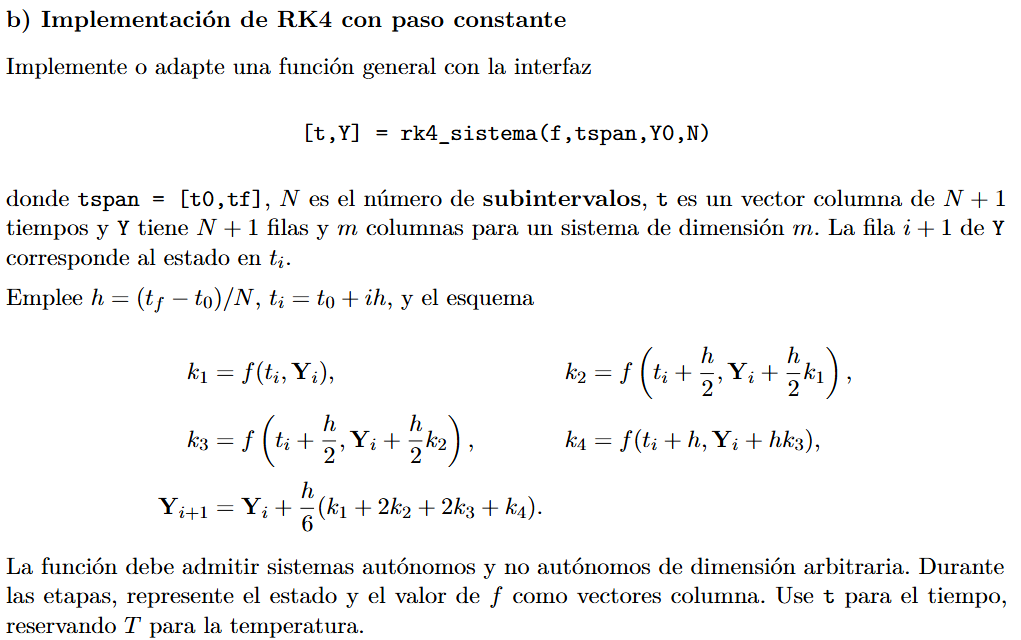

function [t,Y] = rk4_sistema(f,tspan,Y0,N)
    t0 = tspan(1);
    tf = tspan(2);
    h = (tf-t0)/N;
    m = length(Y0);
    t = linspace(t0,tf,N+1)';
    Y = zeros(N+1,m);

    %cond inicial planteada anteriormente en integrante 1
    Y(1,:) = Y0(:)';
   %RK 4to orden
    for i = 1:N
        ti = t(i);
        Yi = Y(i,:)';

        k1 = f(ti,Yi);
        k1 = k1(:);

        k2 = f(ti+h/2,Yi+(h/2)*k1);
        k2 = k2(:);

        k3 = f(ti+h/2,Yi+(h/2)*k2);
        k3 = k3(:);

        k4 = f(ti+h,Yi+h*k3);
        k4 = k4(:);

        Y(i+1,:) = (Yi+(h/6)*(k1+2*k2+2*k3+k4))';

    end
end

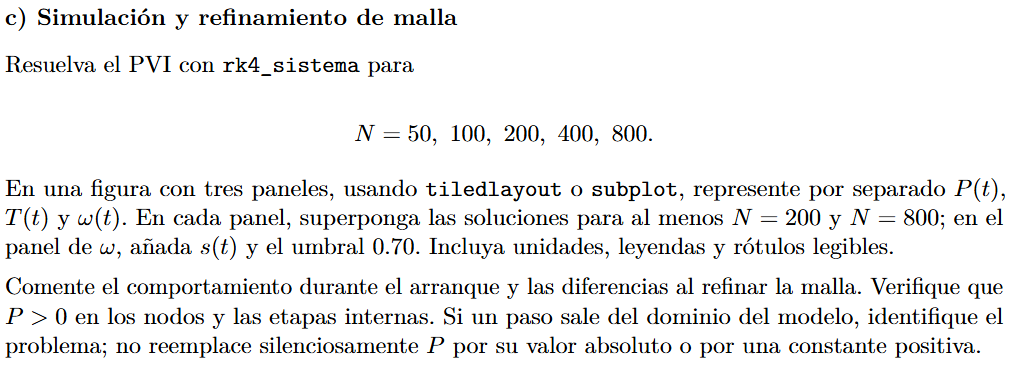

tspan = [t0, tf];
tN = cell(length(Ns),1);
YN = cell(length(Ns),1);
for j = 1:length(Ns)
    N = Ns(j);
    [t,Y] = rk4_sistema(f, tspan, Y0, N);

    tN{j} = t;
    YN{j} = Y;
end

t200 = tN{3};
Y200 = YN{3};

t800 = tN{5};
Y800 = YN{5};

s = @(t) 0.20 + 0.65*(1-exp(-1.10*t));
fig = figure('Visible','off');
tiledlayout(fig,3,1)

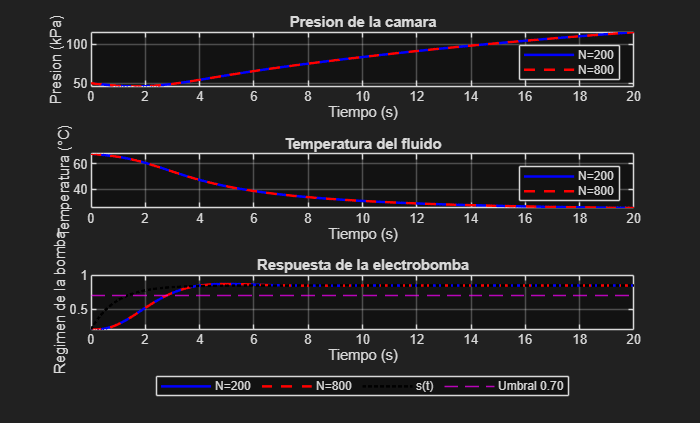

%panel de P de presion (pedido arriba en el enunciado)
nexttile
plot(t200,Y200(:,1),'b','LineWidth',1.5)
hold on

plot(t800,Y800(:,1),'r--','LineWidth',1.5)
xlabel('Tiempo (s)')
ylabel('Presion (kPa)')
title('Presion de la camara')
legend('N=200','N=800')
grid on

%grafica de T de temperatura
nexttile
plot(t200,Y200(:,2),'b','LineWidth',1.5)
hold on
plot(t800,Y800(:,2),'r--','LineWidth',1.5)
xlabel('Tiempo (s)')
ylabel('Temperatura (°C)')
title('Temperatura del fluido')
legend('N=200','N=800')
grid on

%grafica de w de regimen de la bomba propuesta
nexttile

     N       h       Pmin     PresionPositiva
    ___    _____    ______    _______________

     50      0.4    45.951         true      
    100      0.2    45.951         true      
    200      0.1    45.949         true      
    400     0.05    45.945         true      
    800    0.025    45.945         true      



plot(t200,Y200(:,3),'b','LineWidth',1.5)
hold on
plot(t800,Y800(:,3),'r--','LineWidth',1.5)
plot(t800,s(t800),'k:','LineWidth',1.5)
yline(0.70,'m--')
xlabel('Tiempo (s)')
ylabel('Regimen de la bomba')
title('Respuesta de la electrobomba')

P > 0 en todos los nodos.


Las etapas internas de RK4 se evaluaron sin errores de dominio.


legend('N=200','N=800','s(t)','Umbral 0.70', ...
       'Location','southoutside','Orientation','horizontal')
grid on
fig.Visible = 'on';

%verificando si hay presiones positivas o no con una tabla
hvalores = zeros(length(Ns),1);

ans = 4

Pmin = zeros(length(Ns),1);
positiva = false(length(Ns),1);

for j = 1:length(Ns)
    N = Ns(j);

ans = 5


    hvalores(j) = (tf-t0)/N;
    Pmin(j) = min(YN{j}(:,1));
    positiva(j) = all(YN{j}(:,1)>0);
end

tablaPresion = table(Ns',hvalores,Pmin,positiva, ...
    'VariableNames',{'N','h','Pmin','PresionPositiva'});

disp(tablaPresion);

%ultima verificacion explicita como terminaron todos los nodos
if all(positiva)
    disp('P > 0 en todos los nodos.');
    disp('Las etapas internas de RK4 se evaluaron sin errores de dominio.');
else
    error('Se encontraron presiones no positivas en los nodos.');
end

**Discusión del comportamiento durante el arranque y refinamiento de malla**

Durante el intervalo de simulación de 0 a 20 s, la presión parte de 50 kPa, disminuye hasta aproximadamente 45.95 kPa y posteriormente aumenta hasta valores cercanos a 116 kPa. Este comportamiento se relaciona con el incremento progresivo del régimen de la electrobomba, que pasa de 0.20 a aproximadamente 0.85, siguiendo con cierto retraso la señal de mando. Paralelamente, la temperatura disminuye desde 68 °C hasta aproximadamente 25 °C, evidenciando el enfriamiento del fluido.

Respecto al refinamiento de malla, las soluciones obtenidas con N = 200 (h = 0.1 s) y N = 800 (h = 0.025 s) presentan curvas prácticamente superpuestas en las tres variables, lo que indica diferencias visuales pequeñas. Además, la presión mínima calculada pasa de 45.949 kPa a 45.945 kPa, una diferencia de apenas 0.004 kPa. Finalmente, se verificó que P > 0 en todos los nodos y etapas internas de RK4 para las cinco mallas, sin detectar salidas del dominio del modelo.

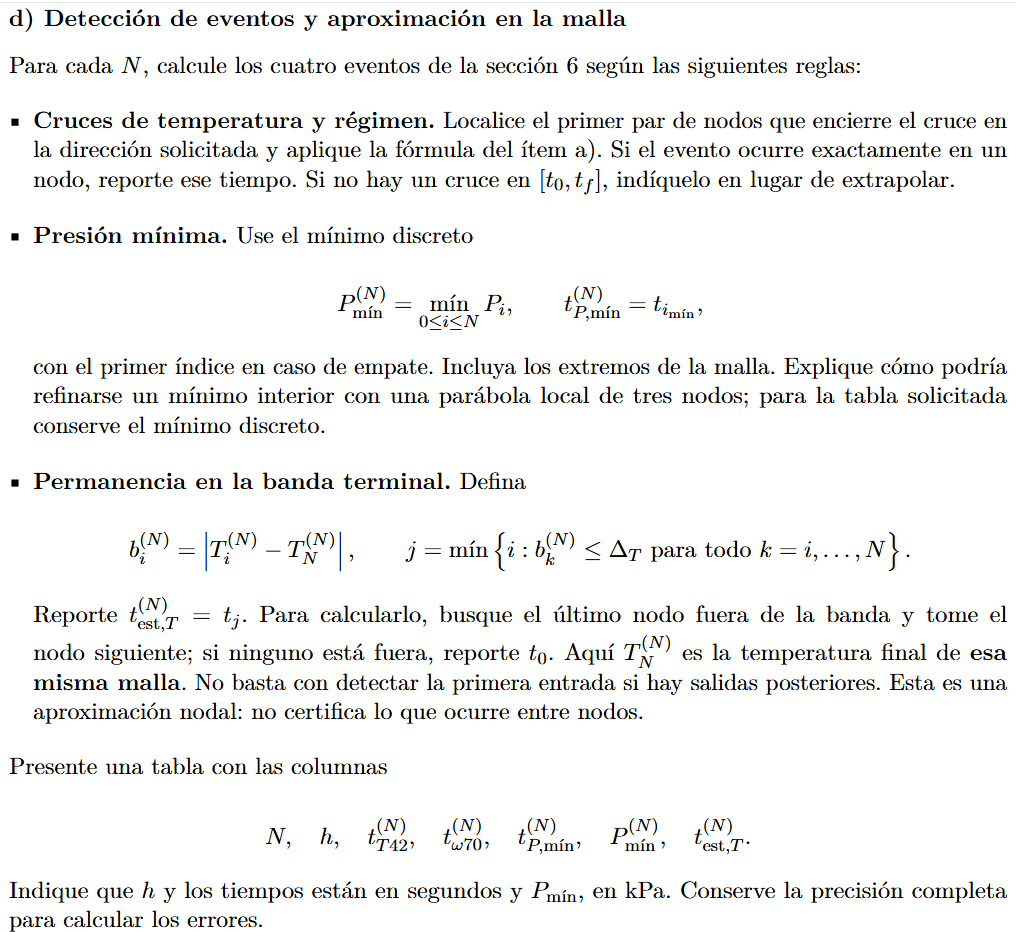

4.


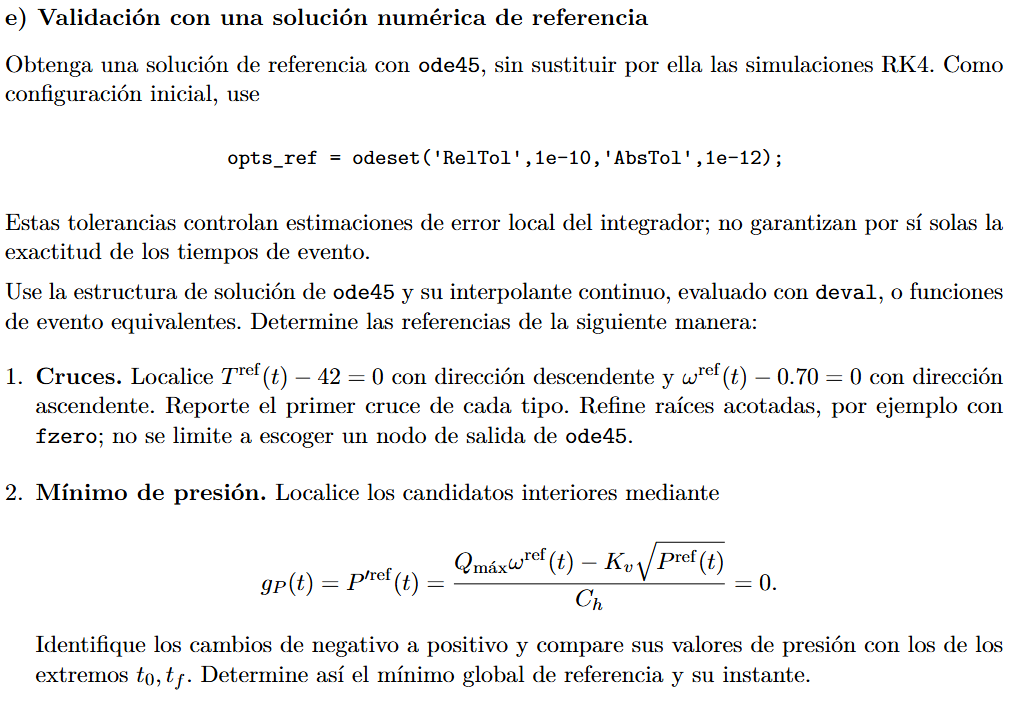

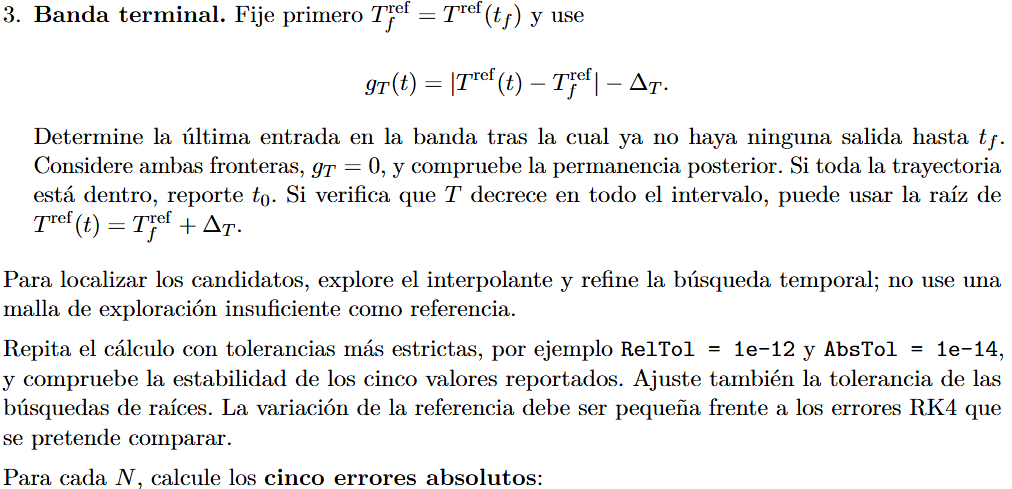

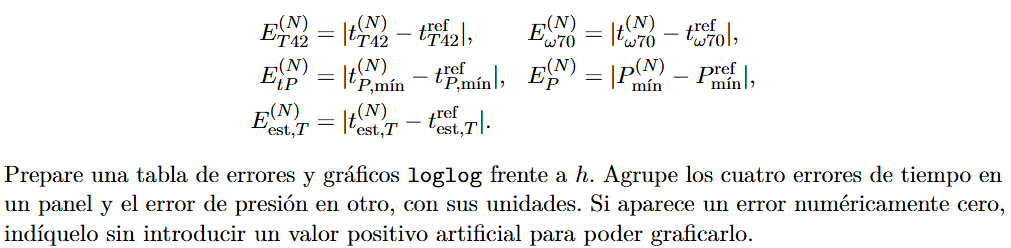

5.


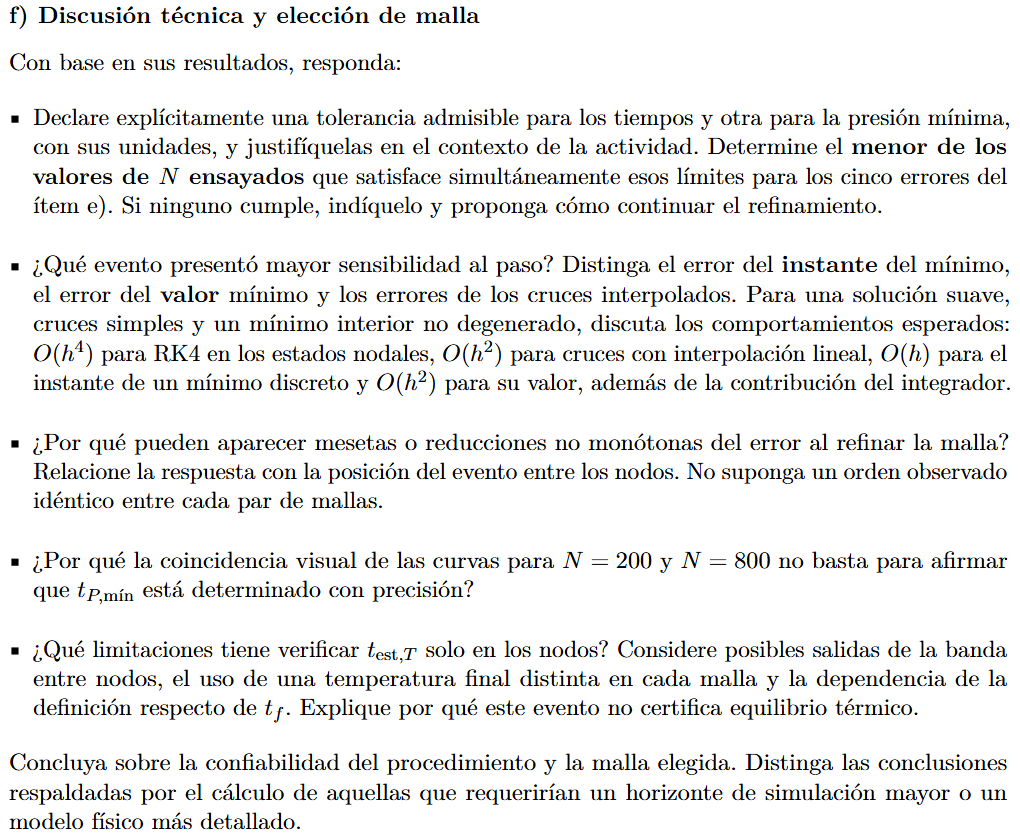



function dY = edo_rc02(t,Y,p)
P = Y(1);  T = Y(2);  w1 = Y(3);  w2 = Y(4);
if ~(P > 0)
    error('RC02:dominio','Fuera del dominio: P = %g kPa <= 0 en t = %.6f s.',P,t);
end
dP  = (p.Qmax*w1 - p.Kv*sqrt(P))/p.Ch;
dT  = p.Qmax*w1/(p.Ch*P)*(p.Tin - T) ...
    + (p.Qgen - p.UAs*(T - p.Tamb))/(p.rho*p.cp*p.Ch*P);
dw1 = w2;
dw2 = (s_mando(t,p) - p.alpha*w2 - w1)/p.tau;
dY  = [dP; dT; dw1; dw2];
end

function s = s_mando(t,p)
s = p.s0 + p.ds*(1 - exp(-p.lam*t));
end


